# Data Visualization: Heatmap Charts

#### by Rodolfo Muñoz

For this example, we're going to analyze the user's engagement in **Twitch's Customer Support**, for that we'll load the dataset **twcs.csv**

clear variables; close all; clc;
[filename,path] = uigetfile('*.xls;*.xlsx;*.csv');

Because of its size, we'll use a datastore where we'll select only the columns related to the chat timestamps

tabds = datastore([path filename]);
tabds.SelectedVariableNames = {'tweet_id','created_at'};
preview(tabds)

ans = 8×2 table
    tweet_id                created_at            
    ________    __________________________________

        1       {'Tue Oct 31 22:10:47 +0000 2017'}
        2       {'Tue Oct 31 22:11:45 +0000 2017'}
        3       {'Tue Oct 31 22:08:27 +0000 2017'}
        4       {'Tue Oct 31 21:54:49 +0000 2017'}
        5       {'Tue Oct 31 21:49:35 +0000 2017'}
        6       {'Tue Oct 31 21:46:24 +0000 2017'}
        8       {'Tue Oct 31 21:45:10 +0000 2017'}
       11       {'Tue Oct 31 22:10:35 +0000 2017'}


We define some variables to delimit our heatmaps and create labels later

months = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};
days = {'Sun','Mon','Tue','Wed','Thu','Fri','Sat'};
wd = 1:7; hh = 0:1:23;
mm = 1:12; dd = 1:31;
A_dd = zeros(31,12);
A_wd = zeros(7,24);
A_mm = zeros(12,31);

With that, we start reading the datastore block by block until all data has been aggregated in variables *A_dd*, *A_wd* and *A_mm*

while hasdata(tabds)
    tab = read(tabds);
    % Process the data to get a datetime array with all data
    dates_raw = strrep(tab.created_at," +0000","");
    dates_raw = extractBetween(dates_raw," ",length(dates_raw{1}));
    dates = datetime(dates_raw,'InputFormat','MMM dd HH:mm:ss yyyy');
    % Extract specific time-parameters
    dates_dd = day(dates);
    dates_mm = month(dates);
    dates_wd = weekday(dates);
    dates_hh = hour(dates);    
    % Accumulate temporal data using histograms
    A_dd = A_dd + hist3([dates_dd dates_hh],'Ctrs',{dd hh(1:2:end)},'CdataMode','auto');
    A_wd = A_wd + hist3([dates_wd dates_hh],'Ctrs',{wd hh},'CdataMode','auto');
    A_mm = A_mm + hist3([dates_mm dates_dd],'Ctrs',{mm dd},'CdataMode','auto');
end

## Use of Heatmap() function

This functions allows to create a heatmap visualization that includes a colorbar very fast and easily, which only requirement is the matrix data and labels for each axis are optional. 

A = A_wd;
A_min = min(A(:));
A_max = max(A(:));
heatmap(hh,days,A,"Title",'Weekly Global Engagement',"CellLabelColor","none");

And now we change the colors to match the style of the reference heatmap of Facebook Global Engagement

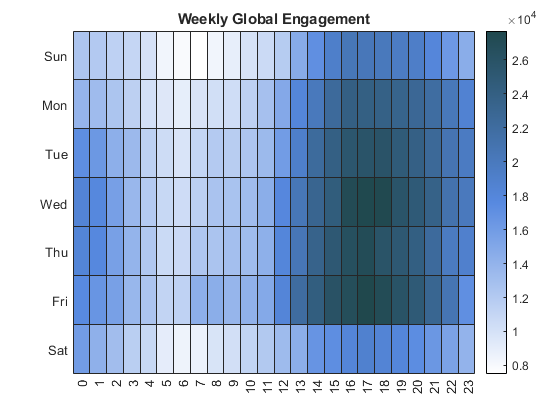

c_top = [32 72 77]/255;
c_mid = [87 137 224]/255;
c_bot = [255 255 255]/255;
color_map = getcolormap(A,[c_top;c_mid;c_bot],'limits',[0 max(A(:))]);
colormap(color_map);

In Matlab 2020b, the using the *heatmap()* function has some cons. Although its easy to use, the heatmap chart is a standalone object and some of its elements cannot be modified, specially the colorbar. Because of that we'll use the function *imagesc()* for all the visualizations, as it allows us to modify all elements easily like when we use a *plot()* function. 

## Weekly Global Engagement

The function *imagesc()* lets us draw a colored matrix similar to the heatmap, but all other aspects such as axis and labels must be customized manually. So we start by plotting a *imagesc()* to see the user's engagement in the twitter's support chat over the week.

A = A_wd; 
A_min = min(A(:));
A_max = max(A(:));
imagesc(hh,wd,A);
title('Weekly Global Engagement')

And now we place the *xticks* and *yticks* half a unit to the side, so the grid divides the image into equally spaced blocks which correspond to the ones painted by *imagesc()*. 

x_Ticks = hh-0.5;
xTickLabels = cellstr(num2str(hh'));
yTicks = wd-0.5;
xticks(x_Ticks);
yticks(yTicks);
grid on;
ax = gca;
ax.GridColor = [1 1 1];

Given the tick positions, the *xticklabels* and *yticklabels *would be placed awkwardly at the start of each block if we used them and that would make reading confusing. To solve that, we'll have to place the labels manually by writting them with the *text()* at the correct locations. 

ax.XAxis.Visible = "off";
ax.YAxis.Visible = "off";
for k = 1:length(x_Ticks)
    txt = text(x_Ticks(k)+0.5,yTicks(end)+1.1,xTickLabels{k},'HorizontalAlignment','center');
end
for k = 1:length(days)
    txt = text(x_Ticks(1)-0.2,yTicks(k)+0.5,days{k},'HorizontalAlignment','right');
end

And finally we setup the *colormap* and *colorbar* so it shows qualitative labels and save the figure.

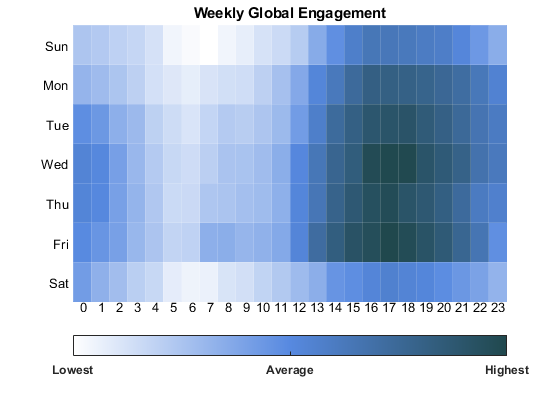

color_map = getcolormap(A,[c_top;c_mid;c_bot],'limits',[0 max(A(:))],'mode','3level');
colormap(color_map);
cb = colorbar;
cb.Location = "southoutside";
cb.Ticks = [A_min (A_max+A_min)/2 A_max];
cb.TickLabels = {'Lowest','Average','Highest'};
cb.FontWeight = "bold";

% fig2pdf("Figures\WeeklyGlobalEngagement");  % To save the figure into a pdf

With that, we can see that the busiest hours are during the evening in working days, specially between 14:00 and 21:00. Also that most of the morning hours have little movement, which is closely related to sleeping hours. 

If we assume that the behaviour of people using the support chat is closely related to their use of twitter and their daily routine, two interesting aspects of daily life can be confirmed by looking at this graph: 

- People getting up later on weekends, by extending very low engagement time periods close to mid-day. 

- People getting more bored at work over the week, by increasing Twitter's usage as Friday closes by.

## Yearly Global Engagement

Similar to the previous heatmap, with the difference that this ones displays engagement in a sort of calendar where each day of the year is presented as a cell. Given that most data from the file tscs.csv is concentrated between October and December, we change the *GridColor* to a dark one so the whole heatmap is visible.

A = A_mm; 
A_min = min(A(:));
A_max = max(A(:));
imagesc(dd,mm,A);
title('Yearly Global Engagement')
x_Ticks = dd(1:end)-0.5;
x_TickLabels = cellstr(num2str(dd'));
y_Ticks = mm-0.5;
xticks(x_Ticks);
yticks(y_Ticks);
grid on;
ax = gca;
ax.GridColor = [0 0 0];

ax.XAxis.Visible = "off";
ax.YAxis.Visible = "off";
axis([0 32 0 13])
for k = 1:2:length(x_Ticks)
    txt = text(x_Ticks(k)+0.5,y_Ticks(end)+1.6,x_TickLabels{k},'HorizontalAlignment','center');
end
for k = 1:length(months)
    txt = text(x_Ticks(1)-0.2,y_Ticks(k)+0.5,months{k},'HorizontalAlignment','right');
end

To vary a little, we also set the colormap to **'5level'** mode so we get a discrete distribution of only 5 colors instead of the usual gradient.

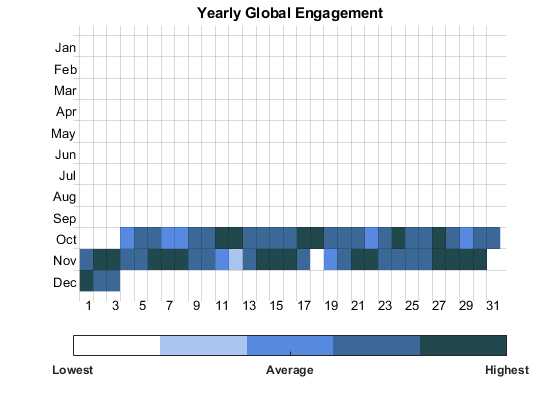

color_map = getcolormap(A,[c_top;c_mid;c_bot],'limits',[0 max(A(:))],'mode','5level');
colormap(color_map);
cb = colorbar;
cb.Location = "southoutside";
cb.Ticks = [A_min (A_max+A_min)/2 A_max];
cb.TickLabels = {'Lowest','Average','Highest'};
cb.FontWeight = "bold";
fig2pdf("Figures\YearlyGlobalEngagement");  % To save the figure into a pdf

## Monthly Global Engagement

Similar to the previous heatmap, with the difference that this ones displays engagement in a sort of calendar where each day of the year is presented as a cell. Given that most data from the file tscs.csv is concentrated between October and December, we change the *GridColor* to a dark one so the whole heatmap is visible.

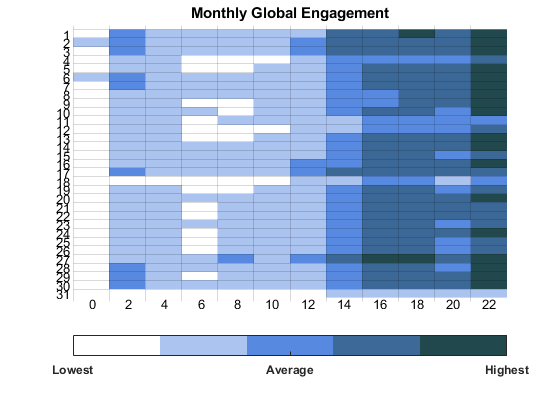

A = A_dd; 
A_min = min(A(:));
A_max = max(A(:));
imagesc(hh(1:2:end),dd,A);
title('Monthly Global Engagement')
x_Ticks = hh(1:2:end)-1;
x_TickLabels = cellstr(num2str(hh(1:2:end)'));
y_Ticks = dd-0.5;
y_TickLabels = cellstr(num2str(dd'));
xticks(x_Ticks);
yticks(y_Ticks);
grid on;
ax = gca;
ax.GridColor = [0 0 0];

ax.XAxis.Visible = "off";
ax.YAxis.Visible = "off";
axis([-1 23 0 32])
for k = 1:length(x_Ticks)
    txt = text(x_Ticks(k)+1,y_Ticks(end)+1.6,x_TickLabels{k},'HorizontalAlignment','center');
end
for k = 1:length(y_Ticks)
    txt = text(x_Ticks(1)-0.1,y_Ticks(k)+0.5,y_TickLabels{k},'HorizontalAlignment','right');
end

color_map = getcolormap(A,[c_top;c_mid;c_bot],'limits',[0 max(A(:))],'mode','5level');
colormap(color_map);
cb = colorbar;
cb.Location = "southoutside";
cb.Ticks = [A_min (A_max+A_min)/2 A_max];
cb.TickLabels = {'Lowest','Average','Highest'};
cb.FontWeight = "bold";